# Dual Cursor Example

This example shows how to use `dualcursor `to add a pair of interactive cursor bars to a plot. Note that this live script likely only works in releases since around R2022a or b. If it doesn't work for you, just save as .m file. Or, just call `help dualcursor `at the command line to get the same examples.

Set up some data:

load handel
Ns = 2^12;
Y = fft(y,Ns);
Y = 2/Ns*abs(Y(1:Ns/2));
df = Fs/Ns;
f = (0:1:Ns/2-1)*df;

## Plot the data

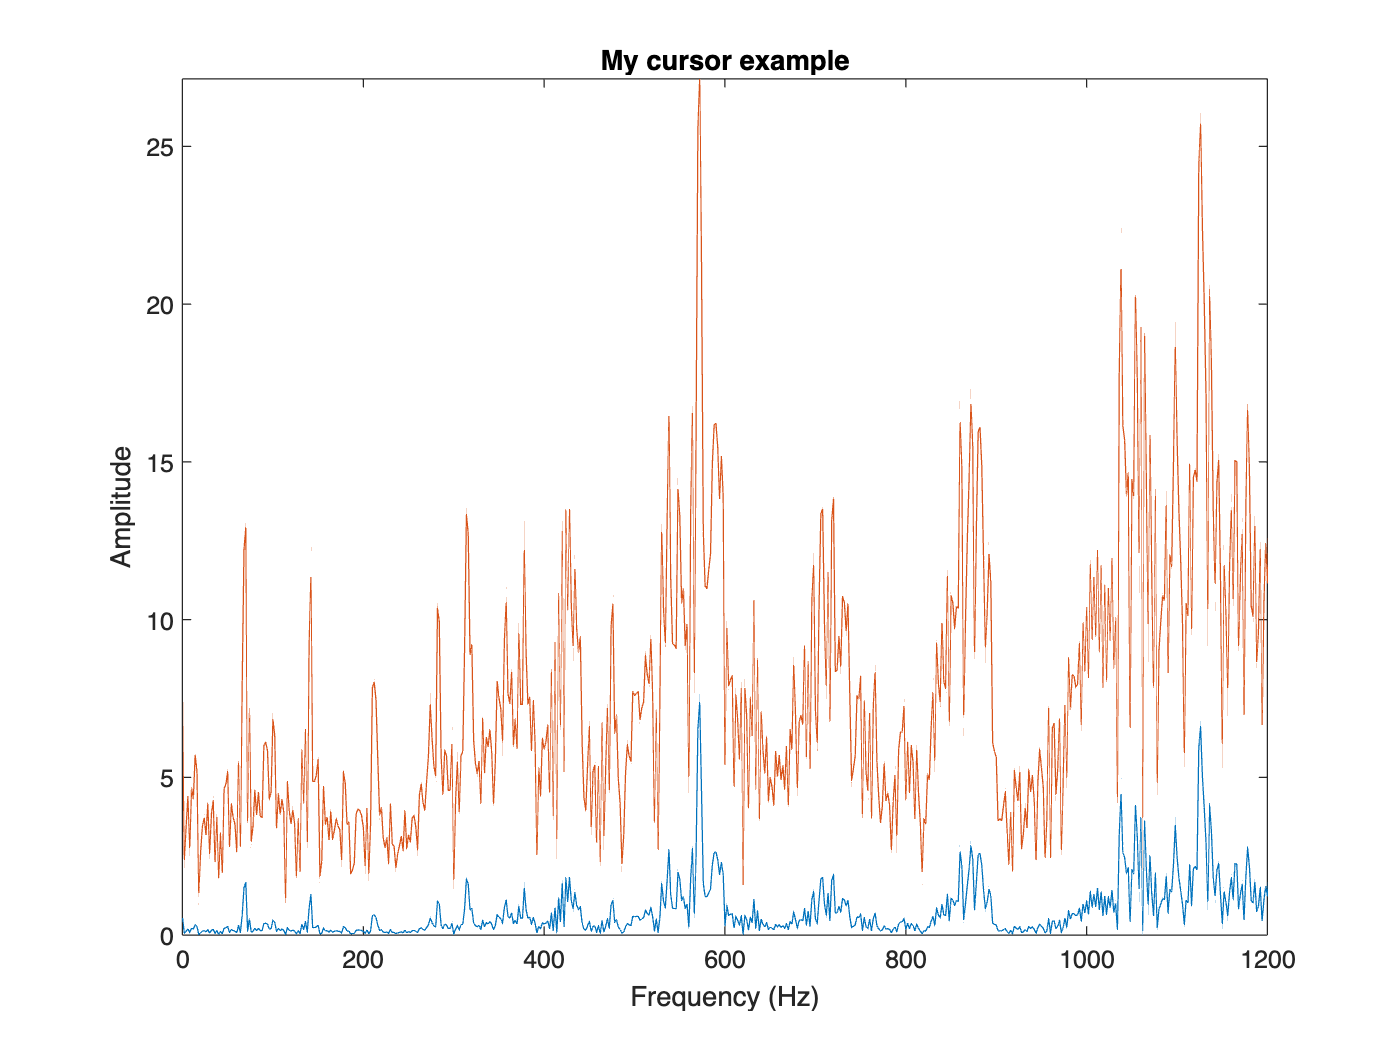

figure;
plot(f,100*[Y sqrt(Y)])
title('My cursor example');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
axis([0 1200 0 inf]);

## Turn on cursors

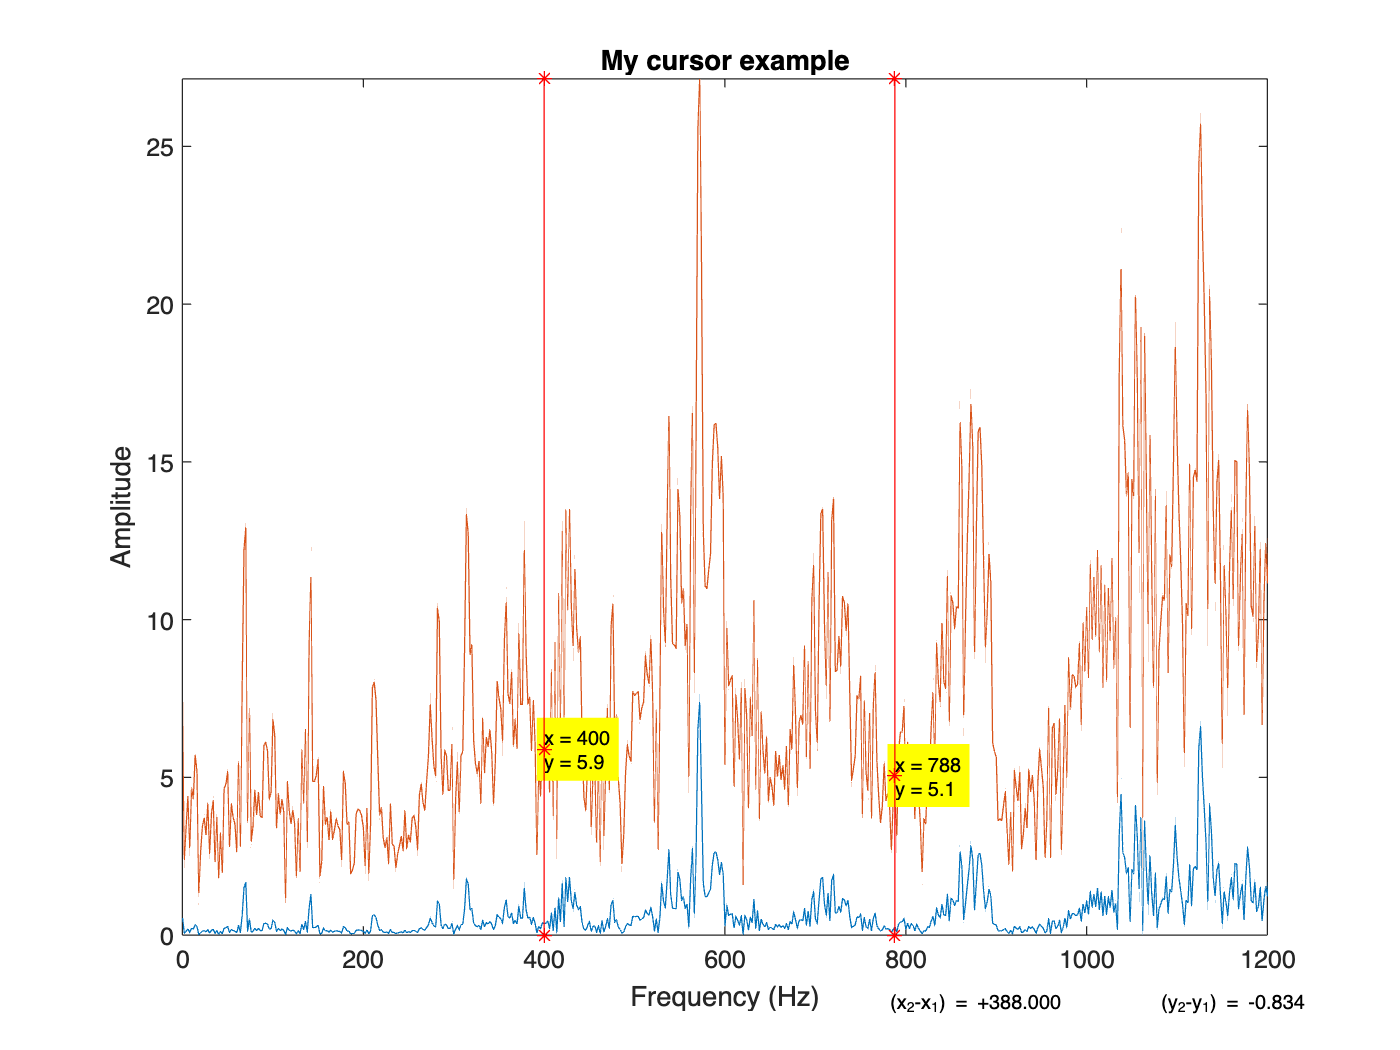

dualcursor on

## Advanced Options

Place cursors at x=100 and x=400, place DeltaX/DeltaY display in the upper left hand corner, and use a green square for the cursor.

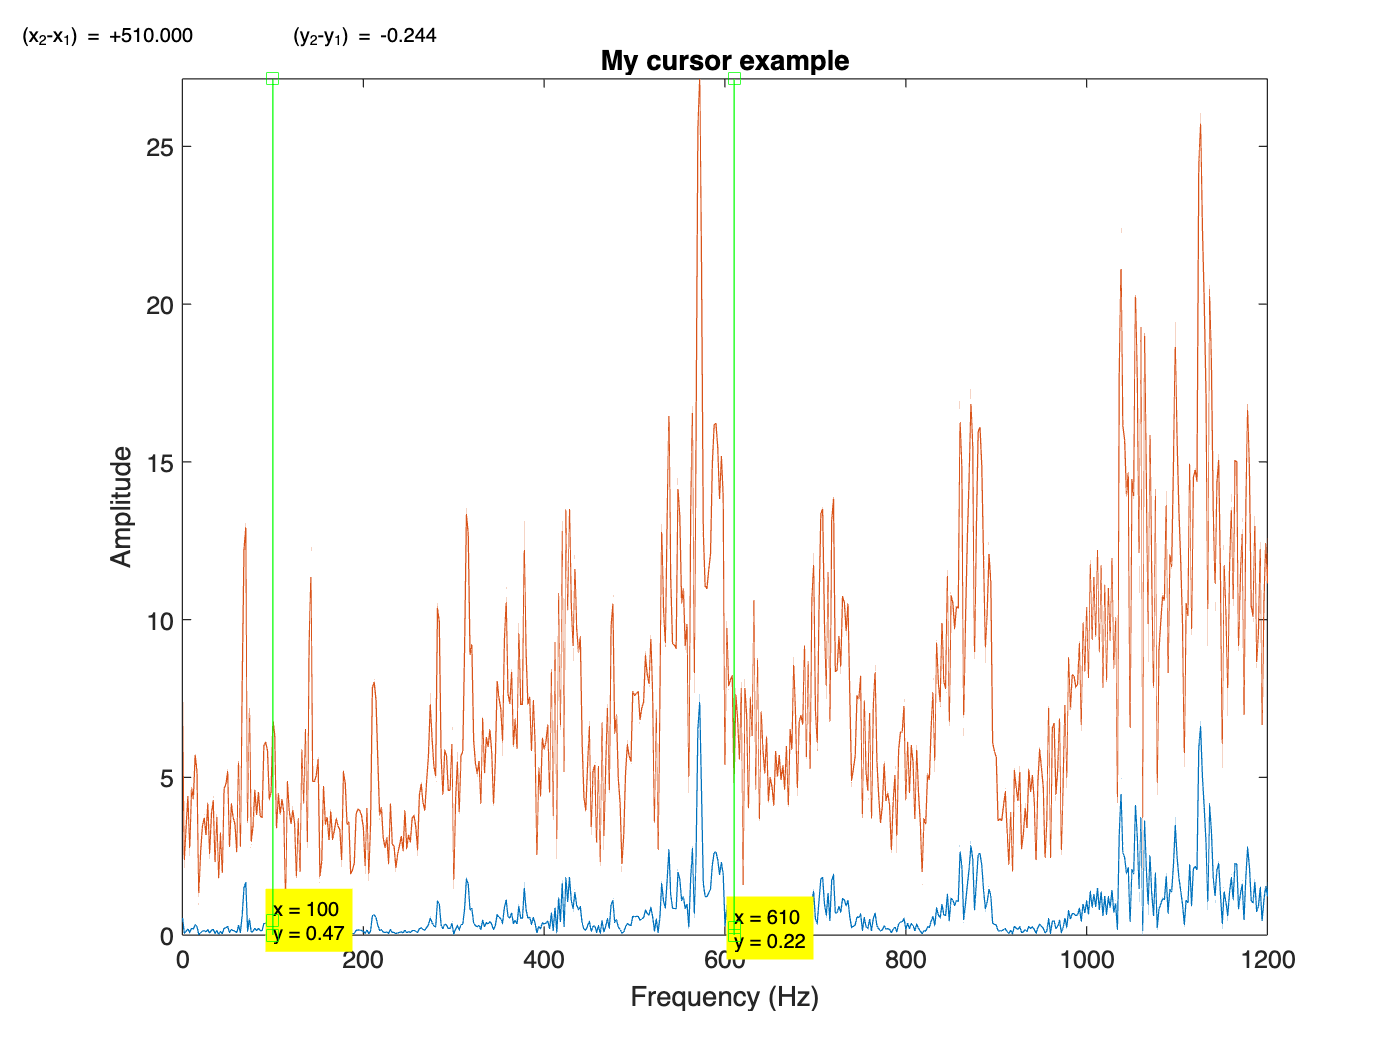

dualcursor off % Turn off existing cursors
dualcursor([100 400],[-.15 1.05; .1 1.05],'gs');